clc; clear all; close all;

N=7;  % input sales data entered for all 7 days in a week
input = [ 9860 6626 8961 5944 8833  ;   
       8099 6182 7425 6086 8471  ;
       9065 5444 6809 6067 7820 ;
       7352 5961 6745 5968 7553 ;
       7349 6145 6796 5524 8581 ;
       4996 4676 4615 5339 5347 ;
       12728 12421 11522 11055 12070  
     ];

for i=1:N
       X(i,:)=((input(i,:)-min(input(i,:)))/(max(input(i,:))-min(input(i,:))));
end

output = [ 6584 ;
          5614 ;
          6705 ;
          5968 ;
          6471 ;
          5383 ;
          13183
    ];

for i=1:N
        D(i,:)=((output(i,:)-min(input(i,:),output(i,:)))/(max(input(i,:),output(i,:))-min(input(i,:),output(i,:))));
end
      
W1 = 2*rand(N, 5) - 1

W1 =    -0.2308    0.9653    0.6355   -0.6425    0.2771
    0.1660    0.4605   -0.4785   -0.1542   -0.9328
   -0.4964   -0.3122    0.1887   -0.8115   -0.8624
   -0.4191    0.1681   -0.9550    0.1970   -0.3608
    0.2342   -0.7845   -0.1495   -0.0582    0.0617
   -0.4694    0.8126   -0.3746    0.3919    0.3089
    0.6488    0.7593   -0.6770    0.3998   -0.1848


W2 = 2*rand(1, N) - 1

W2 =     0.6400    0.4367    0.9373    0.0627   -0.3497   -0.7887    0.2219


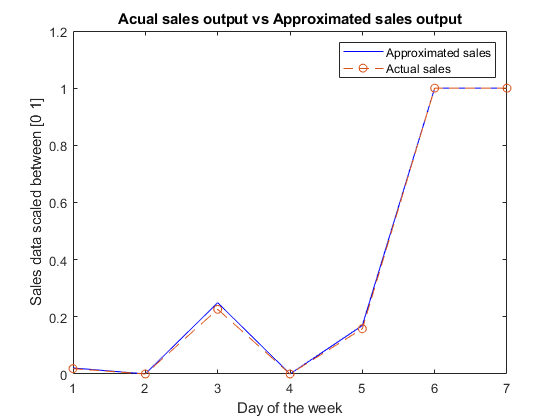


for epoch = 1:10000                    
  [W1 W2] = BackpropCE(W1, W2, X, D, N);
end
                               
for k = 1:N
  x  = X(k, :)';
  v1 = W1*x;
  y1 = Sigmoid(v1);
  v  = W2*y1;
  y(k,1) = (Sigmoid(v));
end

t=1:1:7;
plot(t,y,'b')
title("Acual sales output vs Approximated sales output")
hold on
plot(t,D(:,1),'o--')
legend("Approximated sales","Actual sales")
xlabel("Day of the week")
ylabel("Sales data scaled between [0 1]")
hold off


for i=1:N
        yy(i,:)=y(i,:)*(max(input(i,:),output(i,:))-min(input(i,:),output(i,:)))+min(input(i,:),output(i,:));
        approx(i,:)=sum(yy(i,:))/length(yy(i,:));
end

if sum(X(:,5))<sum(yy)
    disp("The sales would decrease")
elseif sum(X(:,5))>sum(yy)
    disp("The sales would increase")
else 
    disp("There is no much change in sales")
end

The sales would decrease


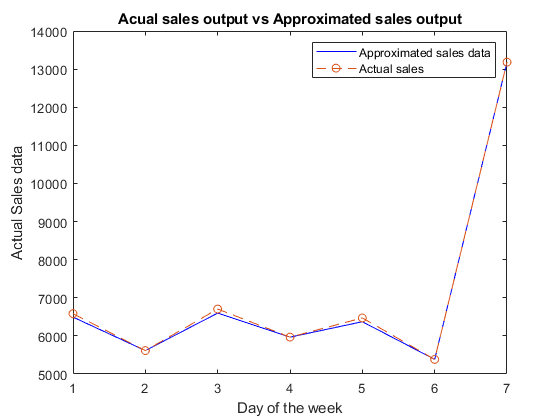


plot(t,approx,'b')
title("Acual sales output vs Approximated sales output")
hold on
plot(t,output(:,1),'o--')
legend("Approximated sales data","Actual sales")
xlabel("Day of the week")
ylabel("Actual Sales data")